# Symbol Mapping and TX Filter Design.  In-Class Problems

## Creating QAM Symbols

The communication toolbox has excellent tools to create QAM symbols.  Suppose we want to modulate `nbits. ` Generate the random bits with the `randi` command.

nbits = 1024;

% TODO.  Generate the random bits 
%    b = randi(...)
b = randi([0,1], nbits, 1);


We want to map `nbitsPerSym=4` bits / symbol.  Find the appropriate QAM order and use the `qammod` function to modulate the bits to complex symbols.  For `qammod` set the `InputType` to `bit` to take a binary sequence and `UnitAveragePower` to true to normalize the symbols.

nbtisPerSym = 4;

% TODO:
%   M = ...
%   s = qammod(b,M,InputType','bit','UnitAveragePower',true);
M = 2^nbtisPerSym;
s = qammod(b,M,'InputType','bit','UnitAveragePower',true);

Plot the consteallation where each symbol `s` is plotted as a dot or circle on the real-imaginary plane.

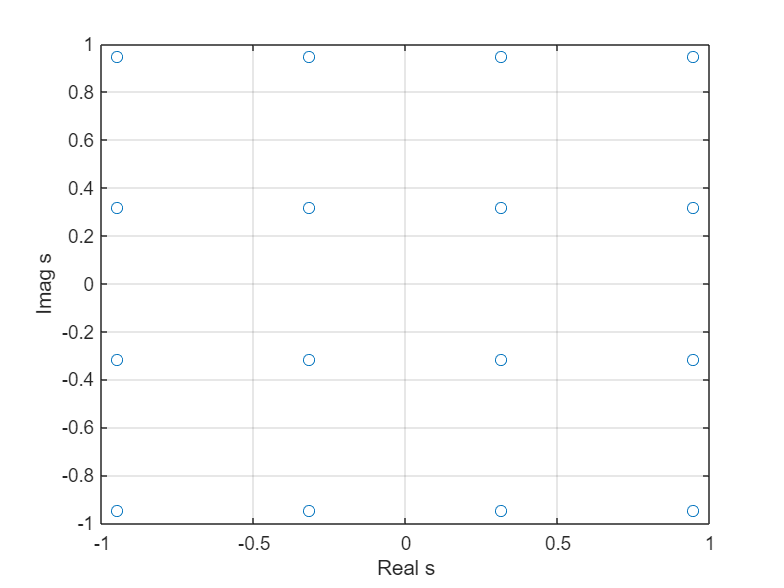

% TODO
%   plot(...);
plot(real(s), imag(s), 'o');
grid on;
xlabel('Real s');
ylabel('Imag s');

## Pulse Shaping with a Raised Cosine Filter

In this section, we will see next perform pulse shaping of the symbols.  We will use a widely-used raised cosine filter.  Complete the code below to create the filter and plot its impulse response.

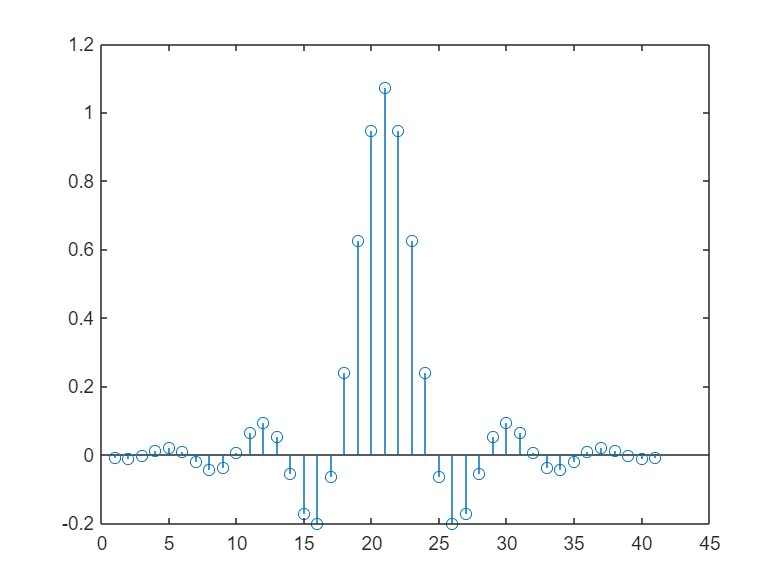

fsym = 20e6;  % Symbol rate 
beta = 0.25;  % Rolloff factor
span = 10;    % Filter length in symbols
sampsPerSym = 4;   % Number of samples per symbol
b = rcosdesign(beta,span,sampsPerSym);

% TODO:  Normalize the filter coefficients so that they have a 
% DC gain = sampsPerSym
b = sampsPerSym* b / sum(b);

% TODO:  Plot the impulse response b using a stem plot
stem(b);

Now compute the sample rate and plot the frequency response using the `freqz` function.  Plot the power gain vs. frequency in MHz 

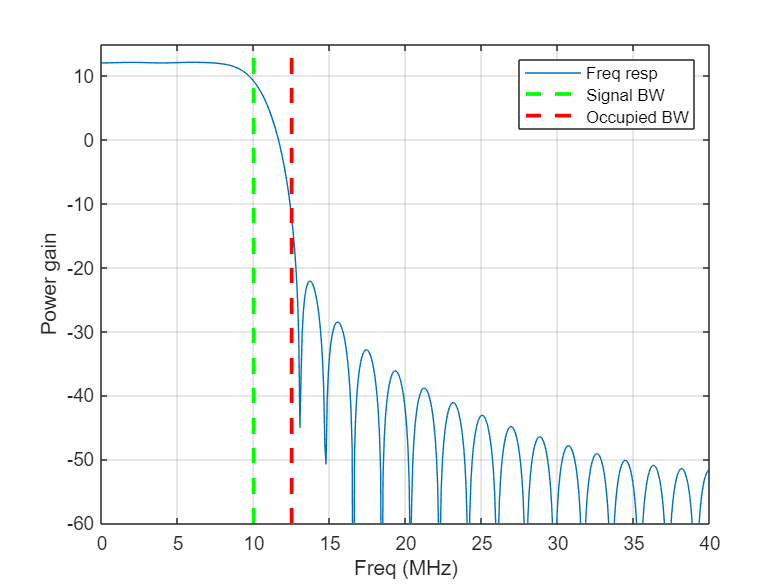

% TODO:  Compute the sample rate from the symbol rate and number of samples
% per symbol
%   fsamp = ...
fsamp = fsym*sampsPerSym;

% TODO:  Compute the frequency response using the freqz function
%   npts = 1024;
%   [h,w] = freqz(...);
npts = 1024;
[h,w] = freqz(b,1);

% TODO:  Plot the frequency response 10*log10(|H(f)|^2) vs. the frequency
% in MHz.
clf;
f = w/2/pi*fsamp;
plot(f*1e-6, mag2db(abs(h)), 'DisplayName', 'Freq resp');
ymin = -60;
ymax = 15;
ylim([[ymin, ymax]]);
grid on;
xlabel('Freq (MHz)');
ylabel('Power gain');

% This was not required but, I added lines to show the signal and occupied
% bandwidths
hold on;
plot([fsym/2, fsym/2]/1e6, [ymin ymax], 'g--', 'LineWidth', 2, 'DisplayName', 'Signal BW');
plot([fsym/2*(1+beta), fsym/2*(1+beta)]/1e6, [ymin ymax], 'r--', 'LineWidth', 2, 'DisplayName', 'Occupied BW');
hold off;
legend();

Perform the filtering by:

- Upsampling the symbols, `s, by sampsPerSym `to create an upsampled version, `s1`.  You can use the `upsample` command.

- Filter `s`1 with the filter `b` to create the upsampled signal x.  

% TODO:
%    s1 = upsample(...);
%    x = filter(...);
s1 = upsample(s, sampsPerSym);
x = filter(b, 1, s1);

Finally, to visualize the constellation:  Create a single plot with the points:

- (Real(x), imag(x)) which represents the filtered points

- (real(s), imag(s)) which represent the original symbols

You should see that the signal `x` goes through the original points `s`

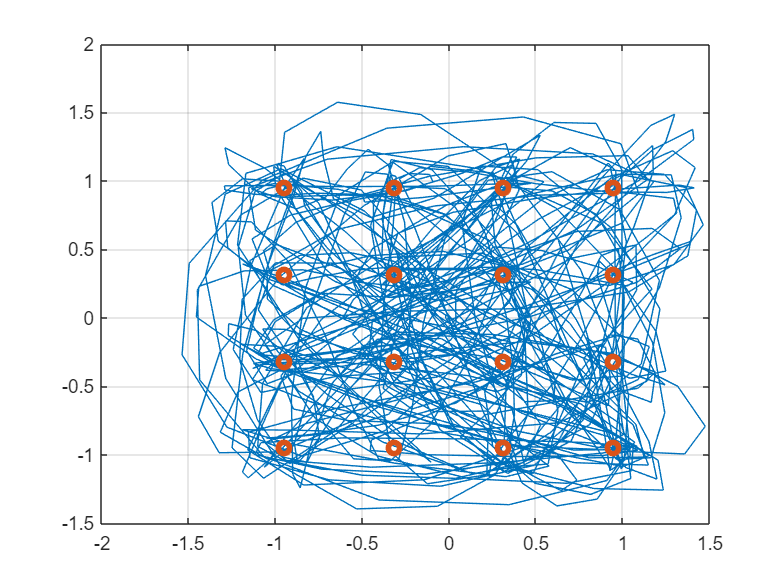

% TODO
%   plot(...);
%   hold on;
%   plot(...);
%   hold off;
plot(real(x), imag(x), '-');
hold on;
plot(real(s), imag(s), 'o', 'Linewidth', 3);
grid on;
hold off;

## Measuring the Power Spectral Density

MATLAB has an excellent tool for measuring the PSD, `pwelch`, based on the Welch algorithm.  It properly normalizes the PSD estmate based on the sampling rate.  It can be called with the following syntax.

window = hamming(512);  % Averaging window
[Px,fx] = pwelch(x,window,[],[],fsamp,'centered');


The above function returns the PSD `Px` in linear scale and frequency `fx.  P`lot the PSD in dBW/Hz vs. frequency in MHz.  It should match the pulse shape frequency response.  Label the axes.

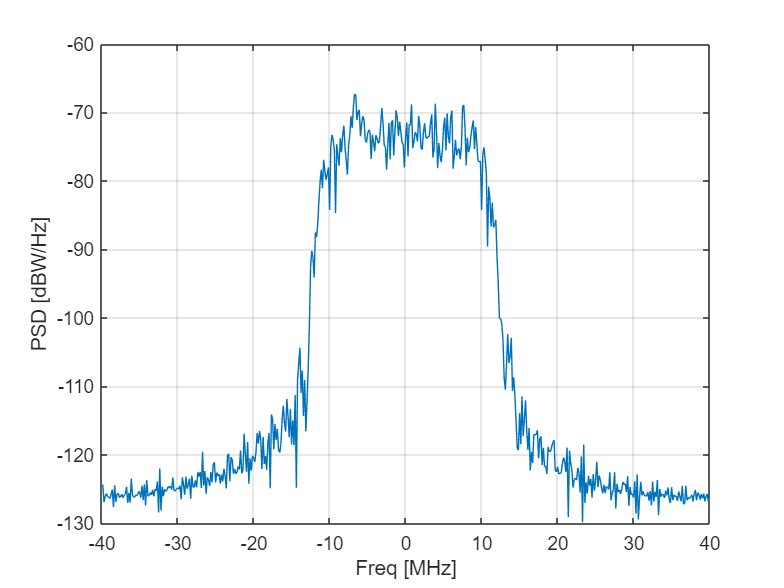

% TODO
%   PxdB = ...
%   plot(...)
PxdB = pow2db(Px);
plot(fx/1e6,PxdB);
xlabel('Freq [MHz]');
ylabel('PSD [dBW/Hz]');
grid on;